## Initialize Directory

defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 2 - P2ry1 Expression');

Error using cd
Cannot CD to M:\Projects and Analysis\Papers\P2ry1\Figure 2 - Gq Pharm and P2ry1 Expression (Name is nonexistent or not a directory).

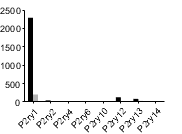

%%All data was obtained from the SHIELD database
%%(https://shield.hms.harvard.edu/) and is data generated from Scheffer et.
%%al, J Neuro, 2015

GFPp = [205.4030432		18.60534812	18.60534812	0.744213925 1.48842785	2.232641774	29.76855699	25.30327344];

GFPn = [2288.325107		43.12134069	13.89143861	2.025834798 8.103339191	129.6534271	85.95327642	7.235124278];

genes = {'P2ry1', 'P2ry2', 'P2ry4', 'P2ry6', ...
    'P2ry10','P2ry12','P2ry13', 'P2ry14'};

figure;
c = categorical(genes);
b = bar([GFPn' GFPp'],1);
xticklabels(genes);
b(2).FaceColor = [.7 .7 .7];
b(1).LineStyle = 'none';
b(1).FaceColor = 'k';
b(2).LineStyle = 'none';
figQuality(gcf,gca,[1.9 1.4]);
xtickangle(45);
export_fig('.\EPS Panels\Gq_expression.eps');

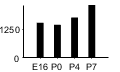

GFPn = [1520.501724 1437.58532 1749.4953 2288.325107];

days = {'E16', 'P0', 'P4', 'P7'};
figure;
c = categorical(days);
b = bar([GFPn'],.4);
xticklabels(days);

b(1).LineStyle = 'none';
b(1).FaceColor = 'k';
figQuality(gcf,gca,[1.5 1.5]/2);
yticks(0:1250:2500)
export_fig('.\EPS Panels\Gq_expression_dev.eps');